# Generate figures 1-6 of the paper Robust Tobit Regression  for Censored Observations Using Extended Box-Cox Transformations 

### Marco Riani, Anthony C. Atkinson, Aldo Corbellini and Gianluca Morelli

Remark: we assume that you have FSDA installed, at least version 8.7.7.5

Simulate the data called "Doubly censored data"    

rng(4)
n=200;
lambda=0;
p=3;
sigma=0.5;
beta=1*ones(p,1);
X=randn(n,p)+1;
epsilon=randn(n,1);

y=X*beta+sigma*epsilon;
y=normYJ(y,1,lambda,'inverse',true,'Jacobian',true);

% Create the double censoring
qq=quantile(y,0.3);
y(y<=qq)=qq;

qq=quantile(y,0.9);
y(y>=qq)=qq;

left=min(y);
right=max(y);

## Create Figure 1. Doubly censored data: yXplot

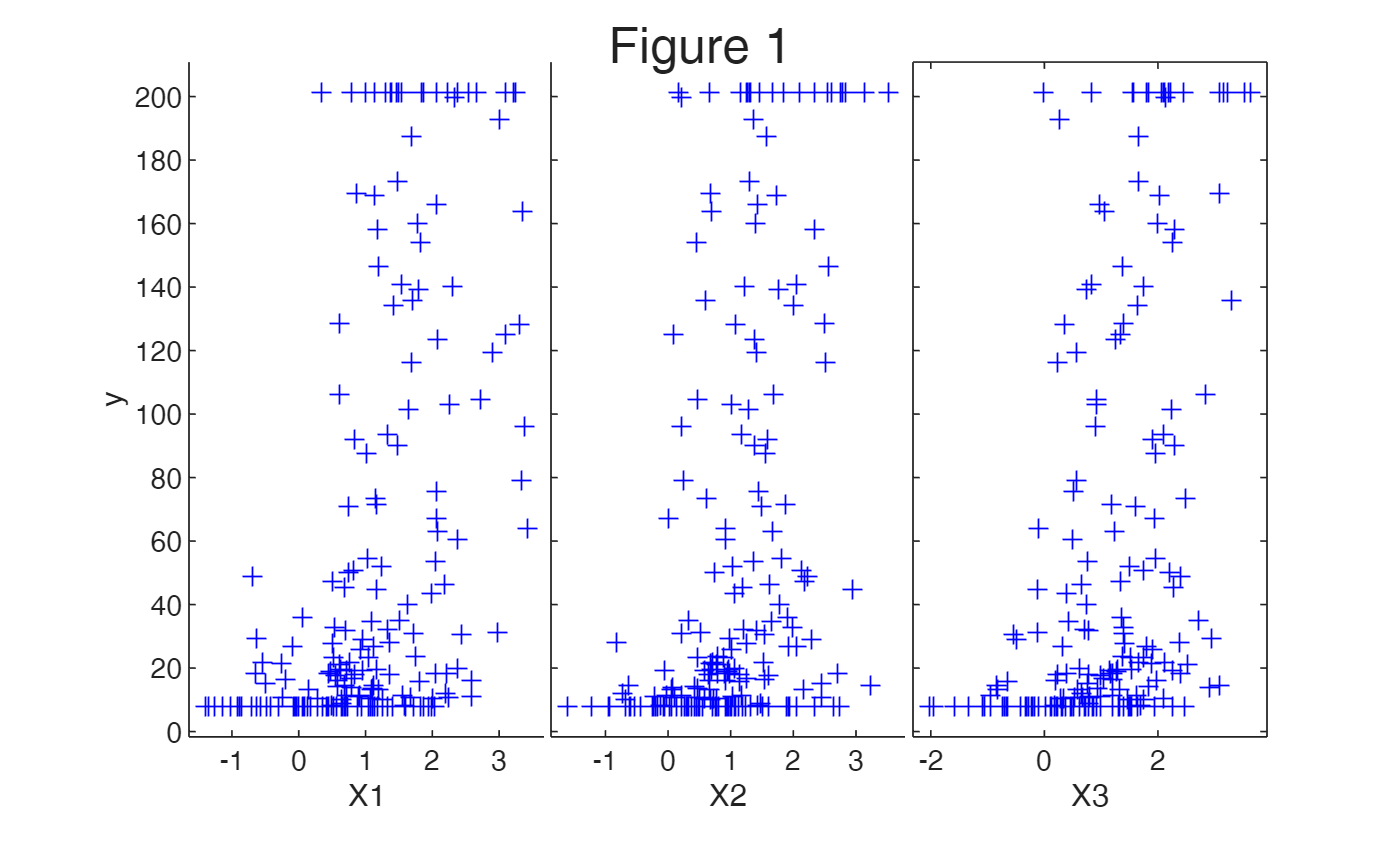

yXplot(y,X);
legend off
prin=0;
if prin==1
    % print to postscript
    print -depsc figs\ULT1.eps;
else
    sgtitle('Figure 1')
end

## Create Figure 2. Doubly censored data: balanced search. Fan plot;

la=-1:0.25:1;
out=FSRfanCens(y,X,'la',la,'left',left,'right',right, ...
    'family','YJ','init',round(n/5),'plots',0);

Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 


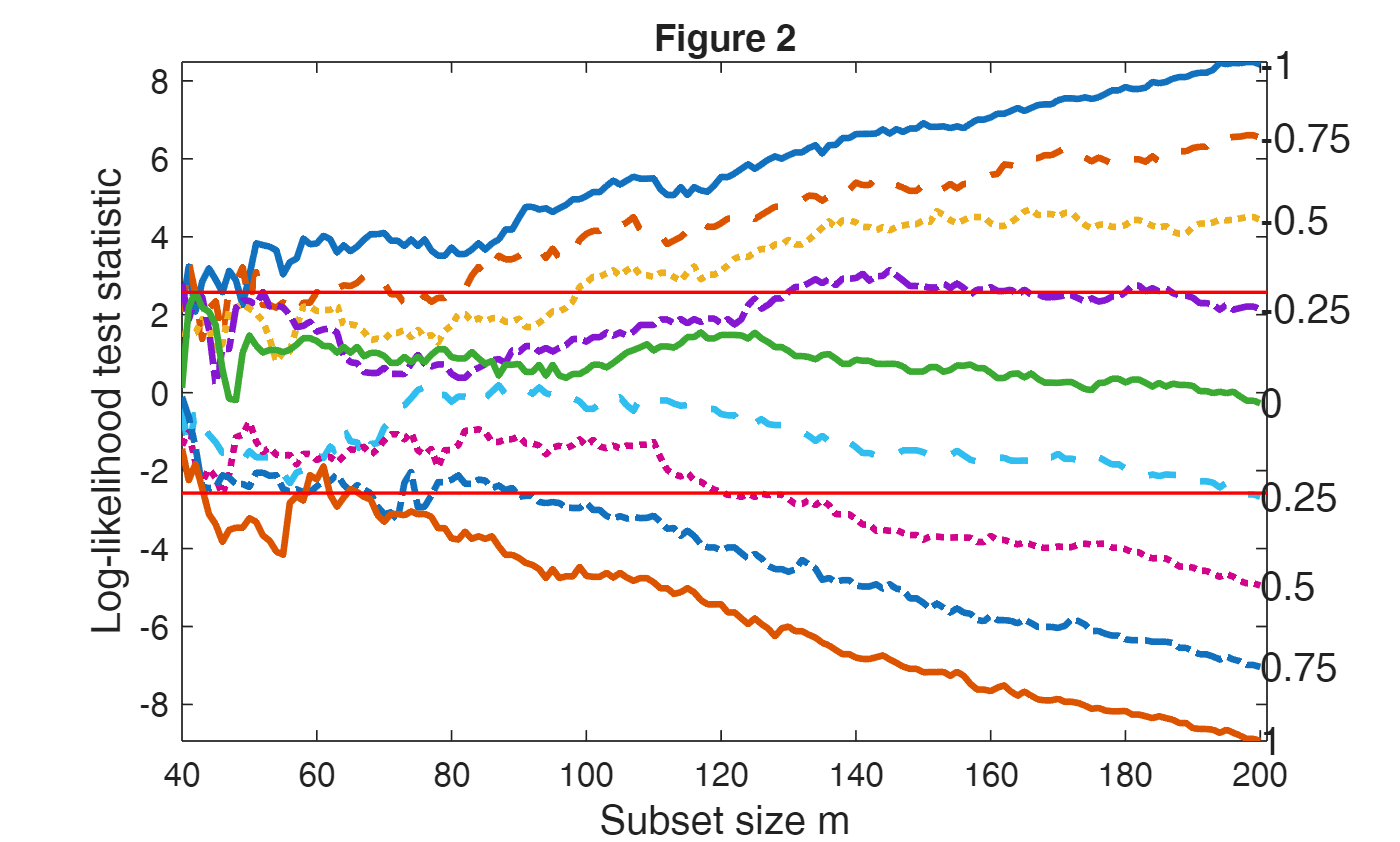

fanplotFS(out);
if prin==1
    title('')
    % print to postscript
    print -depsc figs\ULT2.eps;
else
    title('Figure 2')
end

## Prepare input Figures 3 and 4. Doubly censored data: unbalanced search, λ = 0.

Monitoring residuals with brushing

yf=normYJ(y,1,lambda,'inverse',false,'Jacobian',false);
leftf=normYJ(left,1,lambda,'inverse',false,'Jacobian',false);
rightf=normYJ(right,1,lambda,'inverse',false,'Jacobian',false);

% zlimits=[leftf rightf];
% regressCens(yf,X,'left',min(zlimits),'right',max(zlimits),'dispresults',true)

outLXS=LXS(yf,X,'nsamp',100000);

Total estimated time to complete LMS:  0.56 seconds 



out=FSRedaCens(yf,X,outLXS.bs,'left',leftf,'right',rightf,'init',100);

## Create Figures 3 and 4. Doubly censored data: unbalanced search, λ = 0. Monitoring residuals and brushing

Remark: the interactive version of this Figure is created by file mainSimulatedData_Interactive.m

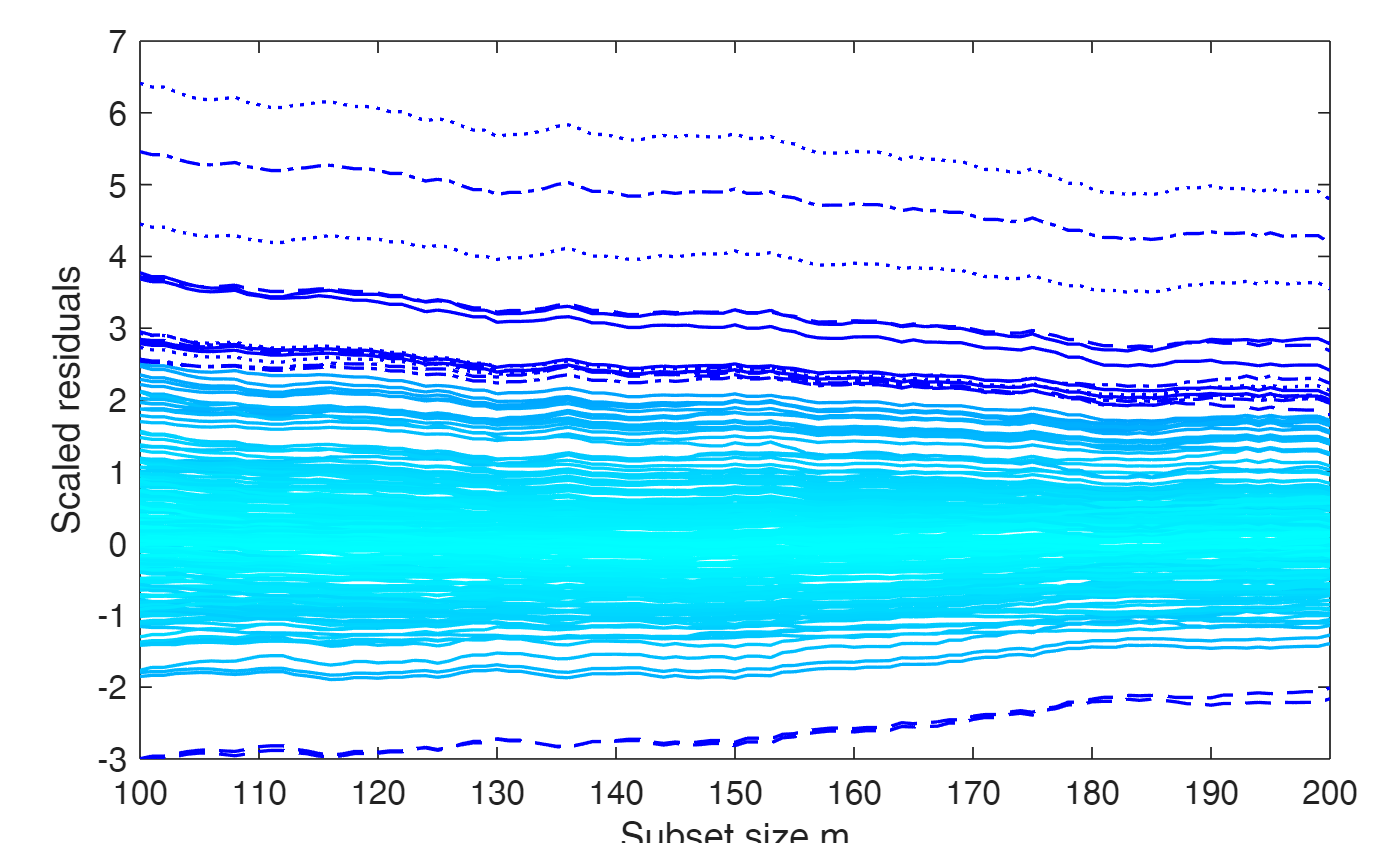

standard=struct;
standard.ylim=[-3 7];
resfwdplot(out,'datatooltip','','databrush','','standard',standard);


if prin==1
    % print to postscript
    print -depsc figs\ULT3a.eps;
    print -depsc figs\ULT3b.eps;

    print -depsc figs\ULT4a.eps;
    print -depsc figs\ULT4b.eps;

end

## Generate the data for example 2: "Outliers and a Lower Threshold"

Simulate the data called "Outliers and a lower threshold"    

rng(2)
n=300;
lambda=-0.5;
p=5;
sigma=0.1;
beta=1*ones(p,1);
X=0.2*randn(n,p);
epsilon=randn(n,1);

y=X*beta+sigma*epsilon;
    y=normYJ(y,1,lambda,'inverse',true,'Jacobian',false);
   
% Contaminate the data
    sel=1:30;
y(sel)=y(sel)+1.2;

qq=quantile(y,0.3);
y(y<=qq)=qq;
left=min(y);
right=Inf;

## Prepare input for Figure 5

Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 
Total estimated time to complete LMS:  0.01 seconds 


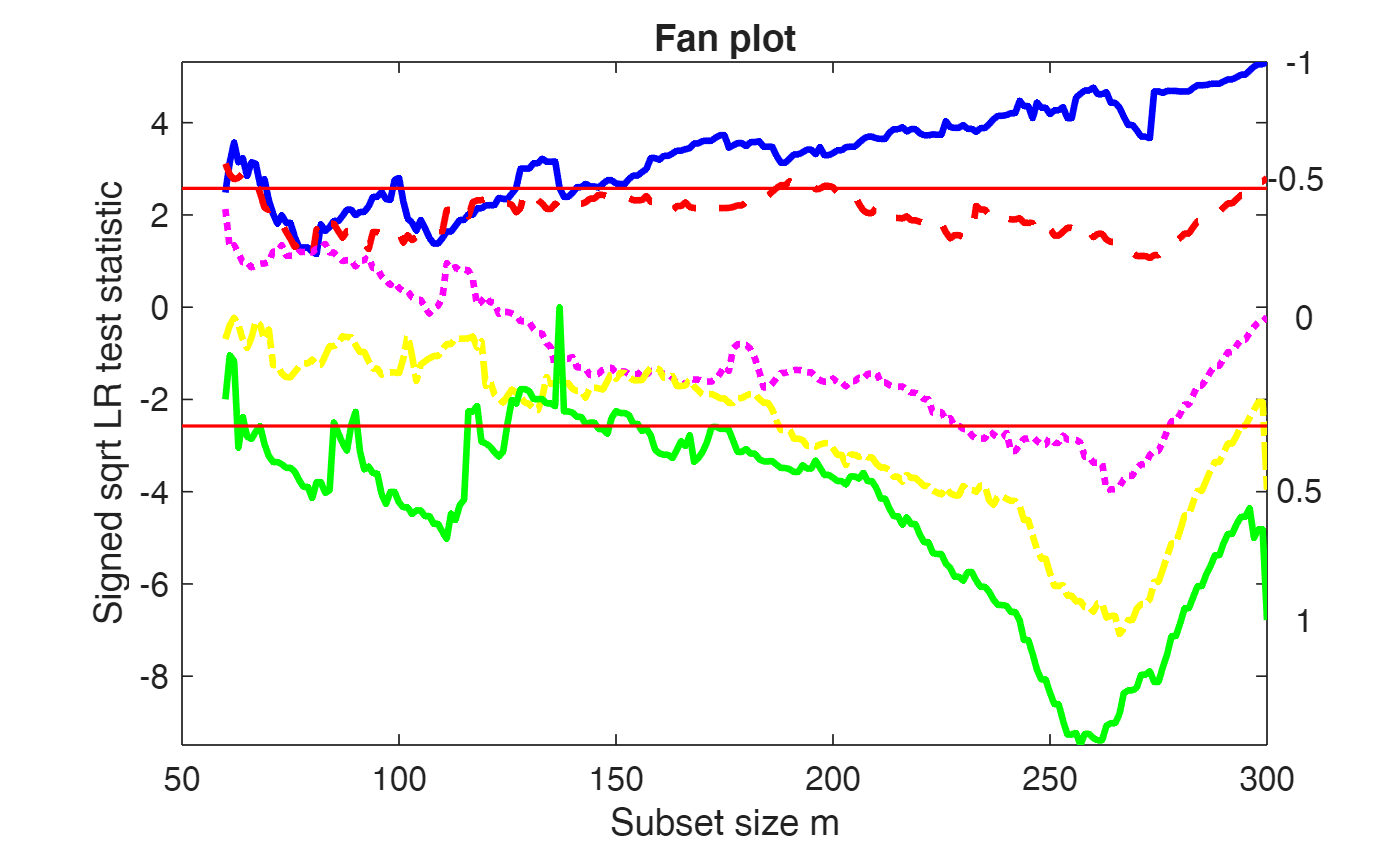

la=-1:0.5:1;
out=FSRfanCens(y,X,'la',la,'left',left,'right',right, ...
    'family','YJ','init',round(n/5));

## Create Figure 5. Outliers and a Lower Threshold: balanced search. Fan plot

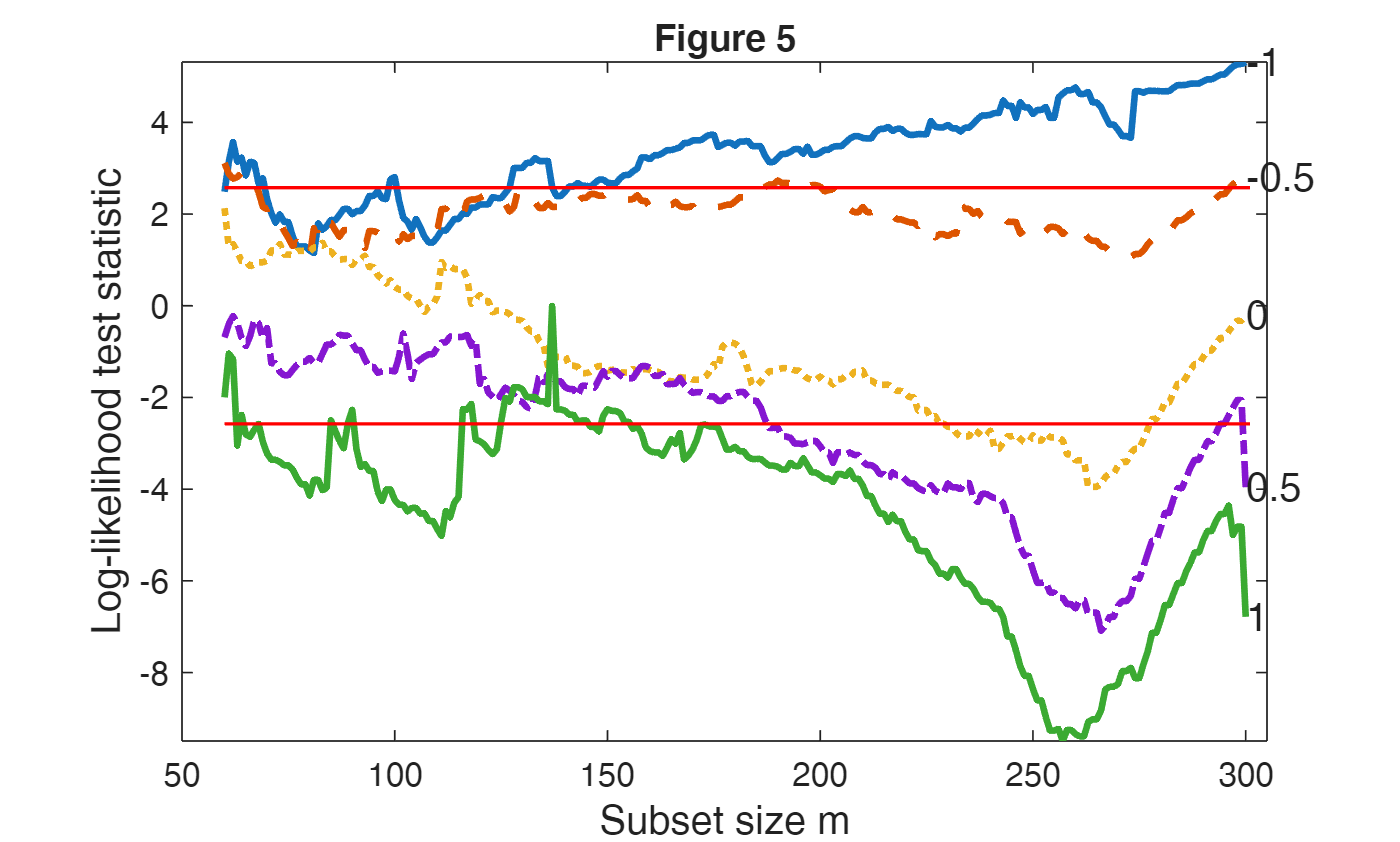

fanplotFS(out);
xlim([50 305])
if prin==1
    title('')
    % print to postscript
    print -depsc figs\LO1.eps;
else
    title('Figure 5')
end

## Prepare input for Figure 6

yf=normYJ(y,1,lambda,'inverse',false,'Jacobian',false);
leftf=normYJ(left,1,lambda,'inverse',false,'Jacobian',false);
rightf=normYJ(right,1,lambda,'inverse',false,'Jacobian',false);

zlimits=[leftf rightf];
%regressCens(yf,X,'left',min(zlimits),'right',max(zlimits),'dispresults',true)

outLXS=LXS(yf,X);

Total estimated time to complete LMS:  0.03 seconds 


warnsing=warning('query','MATLAB:singularMatrix');
warning('off','MATLAB:nearlySingularMatrix');
out=FSRedaCens(yf,X,outLXS.bs,'left',leftf,'right',rightf,'init',100);

m=100
m=200
m=300


warning(warnsing.state,'MATLAB:nearlySingularMatrix');

## Create Figure 6. Outliers and a Lower Threshold: unbalanced search, λ = −0.5. Monitoring residuals 

Remark: the interactive version of this Figure is created by file mainSimulatedData_Interactive.m

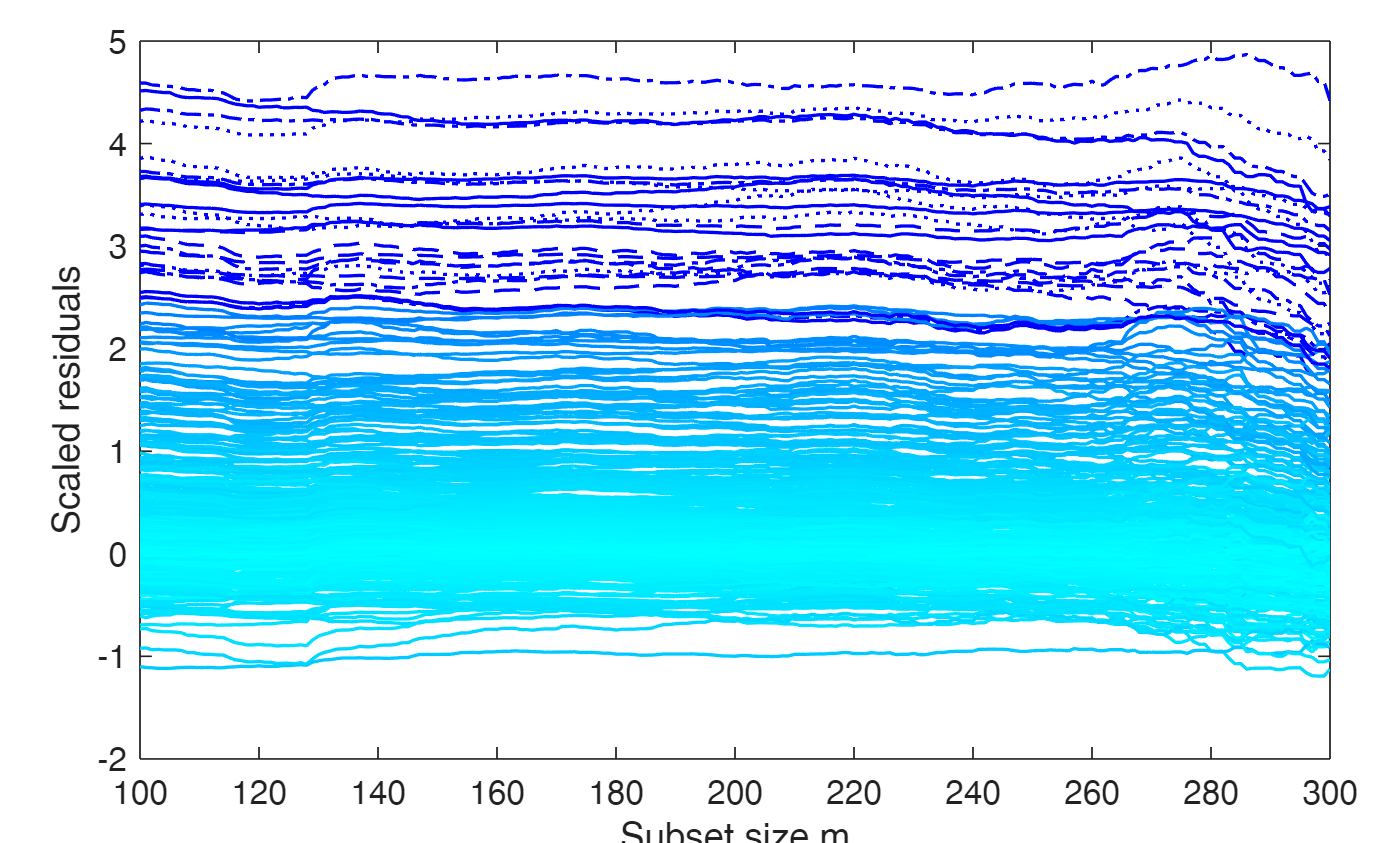

resfwdplot(out,'datatooltip','','databrush','','tag','pltra');


if prin==1
    % print to postscript
    print -depsc figs\LO2a.eps;
    print -depsc figs\LO2b.eps;

end